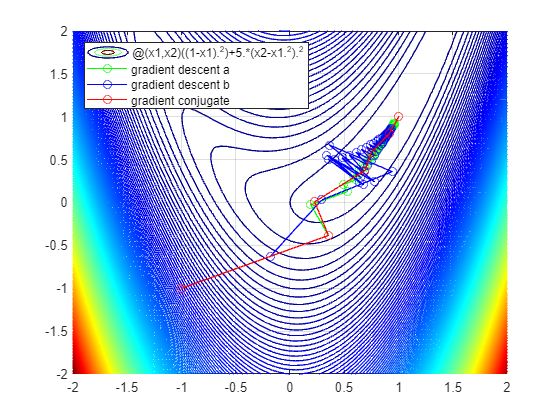

clear;clc;close all;
% Jan Fiala 217141
% Rosenbrock function
ff = @(x1, x2) ((1-x1).^2)+5.*(x2-x1.^2).^2;
syms x1s x2s al
f = (1-x1s)^2+5*(x2s-x1s^2)^2;
% starting point
a = -1; 
b = -1;
% number of iterations
n = 100;

% plot of function
figure(1)=fcontour(ff, [-2 2 -2 2], 'LevelStep', 1);
colormap jet;
grid on;
hold on

% bracketing method
[a1,b1] = gradient_descent_a(f,a,b,n);
plot(a1,b1,'-go')
% decaying stepsize
[a2,b2] = gradient_descent_b(f,a,b,n);
plot(a2,b2,'-bo')
% gradient conjugate
[a3,b3] = gradient_conjugate(f,a,b,n);
plot(a3,b3,'-ro')

leg = legend({func2str(ff),...
    sprintf('gradient descent a'), sprintf('gradient descent b'), ...
    sprintf('gradient conjugate')});
leg.Location = 'northwest';

function [a,b] = gradient_descent_a(f,a,b,n)

syms x1s x2s alg
point(1,1) = a; 
point(2,1) = b;

for k=1:n
%   gradient
    grad = matlabFunction(gradient(f));
    g = grad(point(1,k),point(2,k)); 
    g_norm = g./norm(g);
%   step size
    f_xad = subs(f,[x1s,x2s],[point(1,k) - alg*g_norm(1) ,point(2,k) - alg*g_norm(2)]);
    [alpha(1), alpha(2)] = bracket_minimum(matlabFunction(f_xad),point(1,k));
    [alpha(1), alpha(2)] = fibonacci_search(matlabFunction(f_xad),alpha(1), alpha(2),50);
    alpha = (alpha(1) + alpha(2))/2;
%   new point
    point(:,k+1) = point(:,k) - alpha.*(g_norm);
    
%     if norm(g) < 0.01
%         break
%     end
end
a=point(1,:);
b=point(2,:);
end

function [a,b] = fibonacci_search(f,a,b,n)
par_eps = 1e-2;
fi = (1+sqrt(5))/2; s = (1-sqrt(5))/(1+sqrt(5));
rho = (1-s^n)/(fi*(1-s^(n+1)));
d = rho*b + (1-rho)*a;
yd = f(d);
for i=1:n-1
    if i==n-1
       c= par_eps*a + (1-par_eps)*d;
    else
        c= rho*a + (1-rho)*b;
    end
    yc = f(c);
    if yc < yd
       b = d; d = c; yd = yc;
    else
        a = b; b = c;
    end
    rho = (1-s^(n-i))/(fi*(1-s^(n-i+1)));
end
if a < b
   return
else
    temp = a; a = b; b = temp; 
end

end

function [a,b] = golden_section_search(f,a,b,n)
fi = (1+sqrt(5))/2;
rho = fi - 1;
d = rho*b + (1-rho)*a;
yd = f(d);
for i=1:n-1
   c = rho*a+(1-rho) *b;
   yc = f(c);
   if yc < yd 
      b = d; d = c; yd = yc;
   else
       a = b; b = c;
   end   
end

if a < b
   return
else
    temp = a; a = b; b = temp; 
end

end

function [a,b] = gradient_descent_b(f,a,b,n)

point(1,1) = a; 
point(2,1) = b;

for k=1:n
%   gradient
    grad = matlabFunction(gradient(f));
    g = grad(point(1,k),point(2,k)); 
    normalized_g = g./norm(g);
%   step size
    alpha = 0.9^k;
%   new point
    point(:,k+1) = point(:,k) - alpha.*(normalized_g); 
end
a=point(1,:);
b=point(2,:);
end

function [a,b] = gradient_conjugate(f,a,b,n)
    syms x1s x2s al
    point(1,1) = a; 
    point(2,1) = b;
    g = [[inf; inf] [inf; inf]];
    d = [[inf; inf] [inf; inf]];

    for k=1:n
%       gradient
        grad = matlabFunction(gradient(f));
        g(:,2) = grad(point(1,k),point(2,k)); 
 
        if k==1
            d(:,2) = -g(:,2);
        else
            beta = (transpose(g(:,2))*(g(:,2)-g(:,1)))/(transpose(g(:,1))*g(:,1));
            d(:,2) = -g(:,2) + beta*d(:,1);
        end
 
        f_x = subs(f,[x1s,x2s],[point(1,k) + al*d(1,2) ,point(2,k) + al*d(2,2)]);
        [alpha(1), alpha(2)] = bracket_minimum(matlabFunction(f_x),point(1,k));
        [alpha(1), alpha(2)] = golden_section_search(matlabFunction(f_x),alpha(1), alpha(2),50);
        alpha = (alpha(1) + alpha(2))/2;
 
        point(:,k+1) = point(:,k) + alpha.*d(:,2); 

        d(:,1) = d(:,2);
        g(:,1) = g(:,2);
    end
    a=point(1,:);
    b=point(2,:);
end
